# HW 12 - Nonlinear Regression

## Prob 1

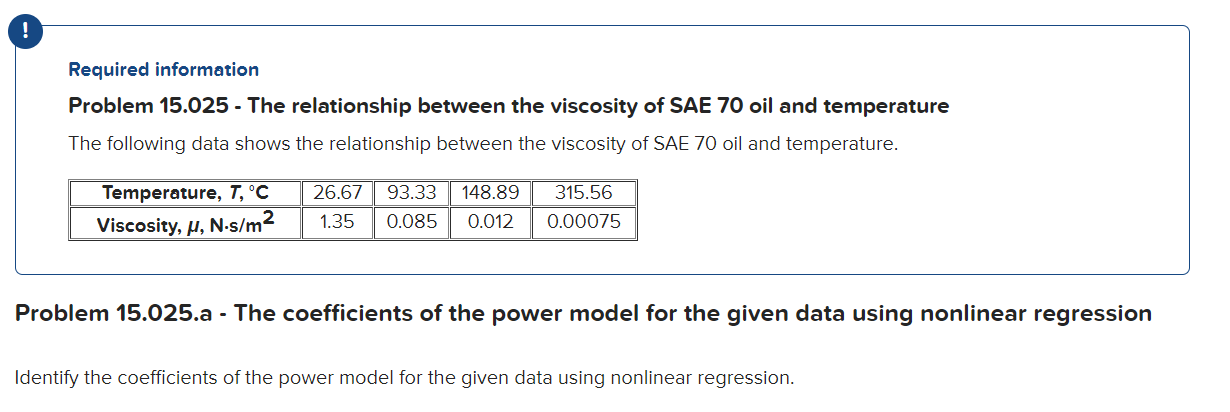

## Prob 2

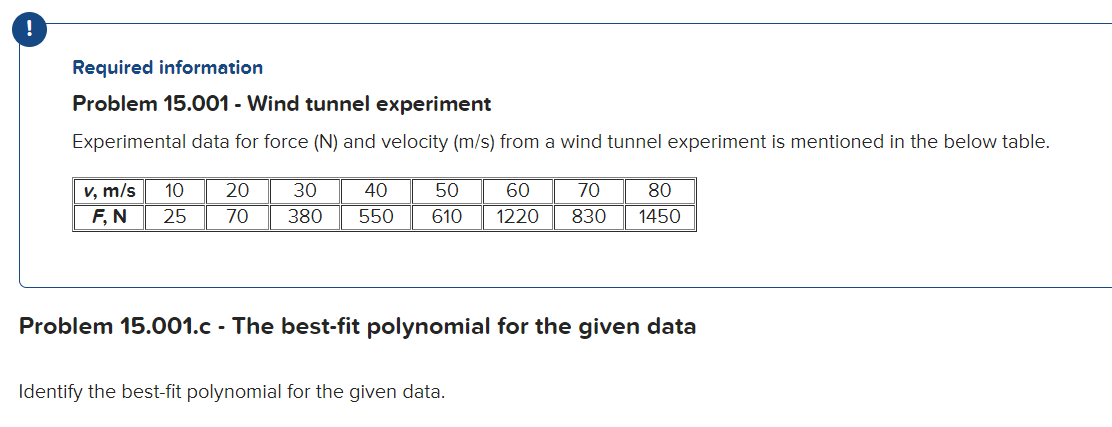

% Find r^2 for nonlinear model, parabolic fit
v = [10, 20, 30, 40, 50, 60, 70, 80];
F = [25, 70, 380, 550, 610, 1220, 830, 1450];

% Polyfit
help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

[p,s] = polyfit(v, F, 2)     % quadratic fit

p =     0.0372   16.1220 -178.4821


s = struct with fields:
           R: [3×3 double]
          df: 5
       normr: 462.3776
    rsquared: 0.8818

F_pred = polyval(p, v)   % predicted values

F_pred = 1.0e+03 *

   -0.0135    0.1588    0.3387    0.5259    0.7206    0.9228    1.1324    1.3494



% Fitnlm
% Define model: F = a1 * v^a2
modelfun = @(b,x) b(1) + b(2)*x + b(3)*x.^2;

beta0 = [1 1 1];
nlm = fitnlm(v,F,modelfun,beta0)

nlm = Nonlinear regression model:
    y ~ b1 + b2*x + b3*x^2

Estimated Coefficients:
          Estimate      SE        tStat      pValue 
          ________    _______    ________    _______
    b1     -178.48     288.49    -0.61868    0.56322
    b2      16.122     14.708      1.0961      0.323
    b3    0.037202    0.15954     0.23319    0.82486

Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 207
R-Squared: 0.882,  Adjusted R-Squared 0.834
F-statistic vs. constant model: 18.6, p-value = 0.00481

## Prob 3

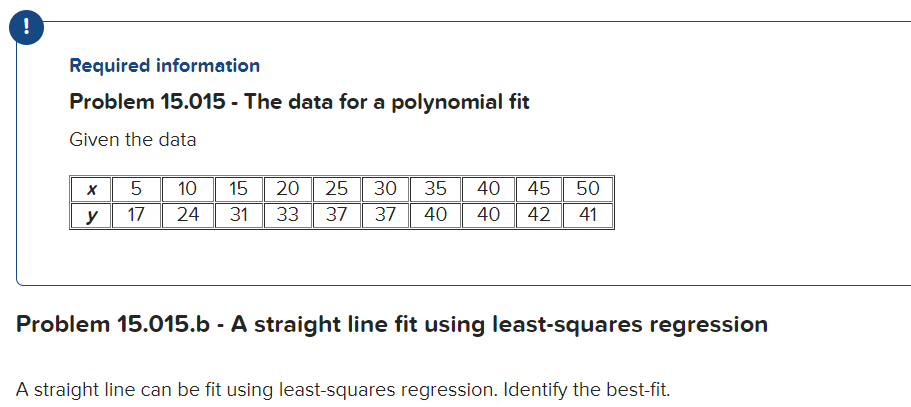

x = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50];
y = [17, 24, 31, 33, 37, 37, 40, 40, 42, 41];

fitlm(x,y)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)       20.6       2.3807    8.6528    2.4723e-05
    x1             0.49455     0.076738    6.4446    0.00019945

Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 3.49
R-squared: 0.838,  Adjusted R-Squared: 0.818
F-statistic vs. constant model: 41.5, p-value = 0.000199


p = polyfit(x,y,1)

p =     0.4945   20.6000



% power equation - WRONG???
modelfun2 = @(b,x) b(1)*x.^b(2);
beta0 = [1 1];
fitnlm(x,y,modelfun2,beta0)

ans = Nonlinear regression model:
    y ~ b1*x^b2

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________
    b1     11.428       1.2805    8.9246    1.9713e-05
    b2    0.34325     0.032695    10.499    5.8958e-06

Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 1.96
R-Squared: 0.949,  Adjusted R-Squared 0.942
F-statistic vs. zero model: 1.59e+03, p-value = 3.94e-11


% linear, then to power eq
% p =        % polyfit(log(x),log(y./x),1);
% y = polyval(p,log(x))

% transform way - RIGHT??
p = polyfit(log10(x),log10(y),1)

p =     0.3851    0.9980


n = p(1)

n = 0.3851

k = 10^(p(2))

k = 9.9529

## Problem 4

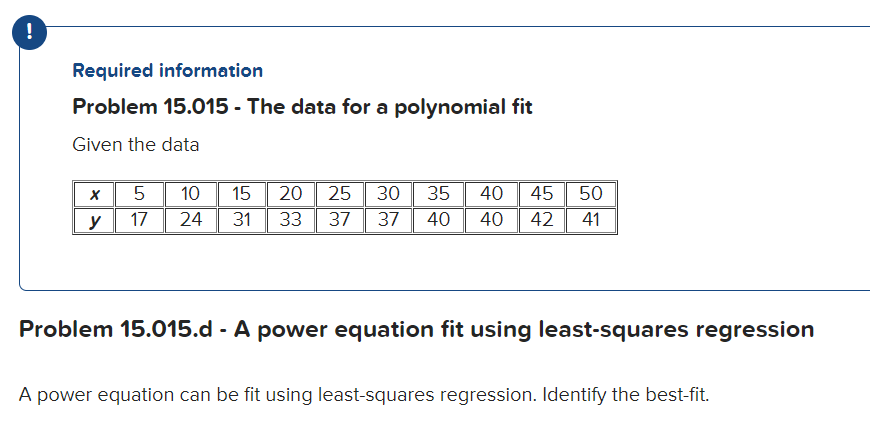

## Prob 5

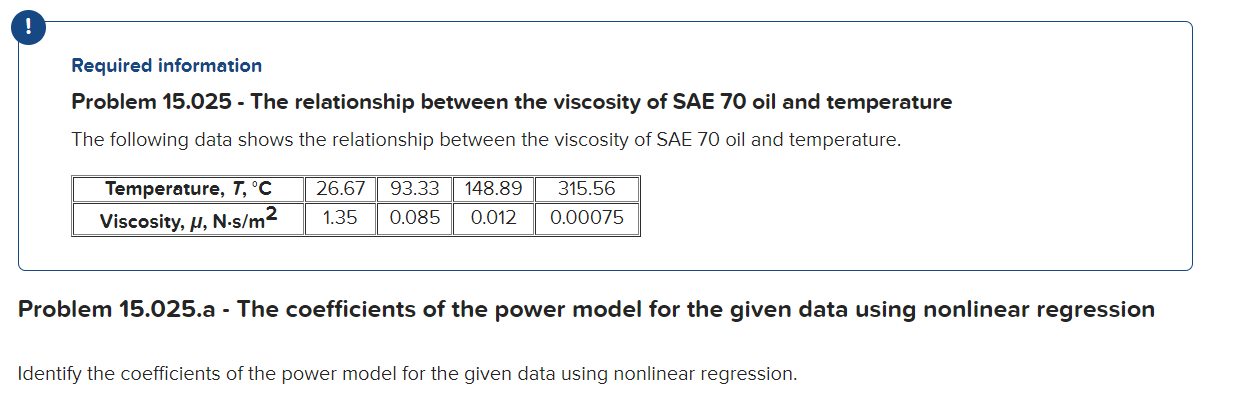

x = [26.67, 93.33, 148.89, 315.56];

ans = Nonlinear regression model:
    y ~ b1*x^b2

Estimated Coefficients:
          Estimate      SE        tStat      pValue  
          ________    _______    _______    _________
    b1     2416.2      885.24     2.7294      0.11211
    b2     -2.281     0.11139    -20.478    0.0023761

Number of observations: 4, Error degrees of freedom: 2
Root Mean Squared Error: 0.012
R-Squared: 1,  Adjusted R-Squared 1
F-statistic vs. zero model: 6.33e+03, p-value = 0.000158

p =    -3.0134    4.5815


n = -3.0134

k = 3.8148e+04

y = [1.35, 0.085, 0.012, 0.00075];

% power equation
modelfun3 = @(b,x) b(1)*x.^b(2);
beta0 = [1 1];
fitnlm(x,y,modelfun3,beta0)

% transform way
p = polyfit(log10(x),log10(y),1)
n = p(1)
k = 10^(p(2))

## Prob 6

clear,clc,clf,format compact
x = [1 2 4 8];
fx = @(x) 10*exp(-0.2*x);
y = fx(x);
help polyint %?? fit or int??

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

yint = polyfit(x,y,3)

yint =    -0.0065    0.1717   -1.9539    9.9760


ytrue = fx(3)

ytrue = 5.4881

et = abs((ytrue - yint) / ytrue)*100

et =   100.1180   96.8713  135.6024   81.7742
